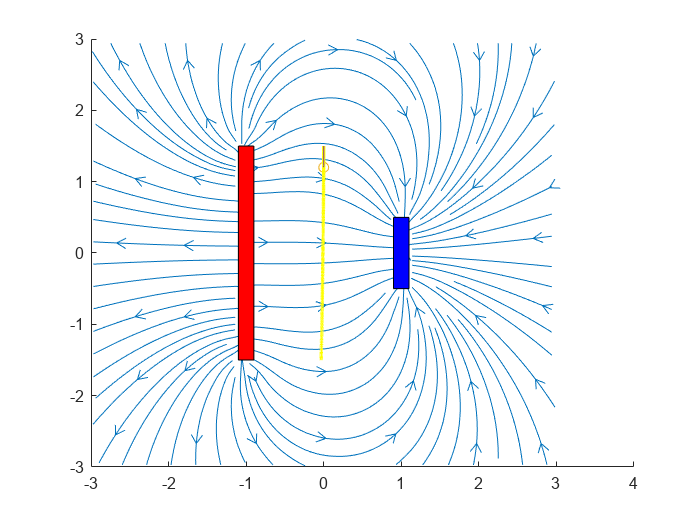

clear
close
clf

%Representacion 3D cargas
pX = 0.2; % mtr
pYPos = 3; % mtr
pYNeg = 1; % mtr
pZ = 1; % mtr
separacion = 1; % mtr

vertices = [-pX/2 1  -pZ/2;
            -pX/2 -1 -pZ/2;
            pX/2  1  -pZ/2;
            pX/2  -1 -pZ/2;
            -pX/2 1   pZ/2;
            -pX/2 -1  pZ/2;
            pX/2  1   pZ/2;
            pX/2  -1  pZ/2];
vertices(:,1) = vertices(:,1) + separacion;

verticesPos = vertices;
verticesPos(:, 2) = (pYPos/2).*verticesPos(:, 2);
verticesPos(:, 1) = -verticesPos(:, 1);

verticesNeg = vertices;
verticesNeg(:, 2) = (pYNeg/2).*verticesNeg(:, 2);

faces = [2 1 3 4;
         6 5 7 8;
         1 2 6 5;
         3 4 8 7;
         1 5 7 3;
         2 6 8 4];

%Vector de Cargas positivas y negativas
nq = 28;
nqBuff = ones(nq,1);
cargasPos = zeros(nq, 3);
cargasPos(:, 3) = nqBuff;
cargasPos(:, 1) = -separacion.*nqBuff;
cargasPos(:, 2) = linspace(-pYPos/2, pYPos/2, nq);
cargasNeg = zeros(nq, 3);
cargasNeg(:, 3) = -nqBuff;
cargasNeg(:, 1) = separacion.*nqBuff;
cargasNeg(:, 2) = linspace(-pYNeg/2, pYNeg/2, nq);

cargas = [cargasPos; cargasNeg];

%Calculo del campo electrico
eps0 = 8.854e-12;
ke = 1/(4*pi*eps0); % N*m^2/C^2
Q = 1; % C
dq = Q/nq; % C
cargas(:, 3) = dq.*cargas(:, 3);

m = 3;
dm = .3;
x = -m:dm:m;
y = -m:dm:m;
[xx, yy] = meshgrid(-m:dm:m, -m:dm:m);

Ex = zeros(size(xx));
Ey = zeros(size(yy));
for i=1:size(cargas, 1)
    cx = cargas(i,1);
    cy = cargas(i,2);
    c = cargas(i,3);
    
    rX = xx-cx;
    rY = yy-cy;
    r3_2 = (rX.^2 + rY.^2).^(3/2);
    Ex = Ex + ((ke*c).*rX./r3_2);
    Ey = Ey + ((ke*c).*rY./r3_2);
end
Emag = sqrt(Ex.^2 + Ey.^2);
Ex = Ex./Emag;
Ey = Ey./Emag;

%Calculo de la trayectoria
qPos =  1; % C
qNeg = -1; % C
pMass = 10; % Kg
pRadi = dm; % mtr
pPos = [0, 1.5]; % mtr
pVel = [0, -1]; % mtr/s
dt = .001; % s
T = 3; % s
time = 0:dt:T;
particleX = [pPos(1) zeros(size(time))];
particleY = [pPos(2) zeros(size(time))];
i = 2;
for t=time
    negX = pPos(1)-pRadi;
    posX = pPos(1)+pRadi;
    %Fuerza en el lado negativo (Izquierda)
    %negF = qNeg.*[interp2(xx,yy,Ex,negX,pPos(2)), interp2(xx,yy,Ey,negX,pPos(2))];
    negF = qNeg.*[interp2(xx,yy,Ex,negX,pPos(2)), 0];
    %Fuerza en el lado positivo (Derecha)
    %posF = qPos.*[interp2(xx,yy,Ex,posX,pPos(2)), interp2(xx,yy,Ey,posX,pPos(2))];
    posF = qPos.*[interp2(xx,yy,Ex,posX,pPos(2)), 0];
    netForce = posF+negF;

    pVel = pVel + ((dt/pMass).*netForce);
    pPos = pPos + (dt.*pVel);
    particleX(i) = pPos(1);
    particleY(i) = pPos(2);
    i = i+1;
end

%Graficacion
hold on
patch('Vertices', verticesPos, 'Faces', faces, 'FaceColor', 'r')
patch('Vertices', verticesNeg, 'Faces', faces, 'FaceColor', 'b')

%quiver(xx, yy, Ex, Ey, 'Color')
streamslice(xx, yy, Ex, Ey)

plot3(particleX, particleY, zeros(size(particleX)), 'y', LineWidth=2)
comet(particleX, particleY);

hold off

title('Simulacion Campo Electrico')
xlabel('X'), ylabel('Y'), zlabel('Z')

axis equal
grid on
box on

xlim([-m,m]), ylim([-m,m])
view([0 90])
